# Discrete Random Variables

***Author****: Ward Nickle, Humboldt State University*

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The   icon refers to an interactive activity that you will find in this script. 

## Probability Distributions

A probability distribution is a table of values that describes every possible value of the random variable and its associated likelihood. Of course, these tables are often equivalently represented by graphs. They are very similar to relative frequency distributions in that, once an experiment is repeated enough times, the empirical probabilities approach the theoretical ones. So, relative frequency distributions with a large enough sample size can be thought of as probability distributions.

Coins, dice, and playing cards are commonly used to describe discrete random variables and their associated probability distributions. For example, if we consider the number of heads in 2 coin tosses, there are a fixed number of possible outcomes and a probability for each. There can only be 0, 1, or 2 heads in 2 coin tosses. The outcomes are as follows. 

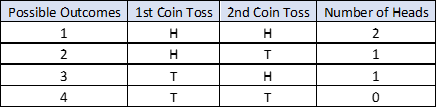 

Now if we consider the probabilities associated with each value of the random variable, number of heads, we see that they occur with the following relative frequencies, which are probabilities.

That is, out of 4 possible outcomes, there is only 1 way to get no heads or both heads, and there are 2 ways to get 1 head. When held relative to the total number of possible outcomes, these counts inform the probability of each particular outcome, P(x). The values of the random variable are mutually exclusive and collectively exhaustive in that the values do not overlap and consider every possibility. Therefore, the probabilities must always add to 1, or 100%, in the sense that every possible outcome has been considered.

## Statistics

Descriptive statistics for discrete random variables are found in a way analogous to finding a weighted mean. The probability of x, P(x), is essentially the weight for each x. Since the sum of the probabilities is 1, we have the following formula for the mean.


$$\mu =\sum_{i=1}^n \left(x_i P\left(x_i \right)\right)$$
 

The variance, and its square root, the standard deviation, are found in a similar manner.

 
$$\sigma^2 =\sum_{i=1}^n \left\lbrack {\left(x_i -\mu \right)}^2 P\left(x_i \right)\right\rbrack$$
            
$$\sigma =\sqrt{\sum_{i=1}^n \left\lbrack {\left(x_i -\mu \right)}^2 P\left(x_i \right)\right\rbrack }$$
 

## Binomial Distributions

The coin toss example considered above is an example of a binomial experiment. As the name implies, there are 2 possible outcomes in a binomial experiment. Other common examples include true or false, yes or no, and success or failure. As with all random variables, these outcomes must be mutually exclusive. Additionally, there must be a fixed number of trials, or repetitions, of the experiment. The probability between trials must be invariant, and the trials must be independent of one another. If these conditions are met, then the probability of a particular number of successes (or failures) can be found using counting principles and the multiplication rule for probability, which lead to the following formula.

 
$$P\left(X=x\right)={}^{\;}_nC^{\;}_x\;\pi^x {\left(1-\pi \right)}^{n-x}$$


Here $C$ is combination, $n$ is the number of trials, $x$ is the number of successes, and $\pi$ is the probability of success. Therefore, $\left(1-\pi \right)$ is the probability of failure. If in $n$ trials there are $x$ successes, then there are $n-x$ failures. So there are ${}^{\;}_nC^{\;}_x$ ways of distributing $x$ successes in $n$ trials, times the probability of success raised to the number of successes, times the probability of failure raised to the number of failures.

The mean, variance, and the standard deviation can be found more concisely than by using the formulas previously given for discrete random variables.


$$\mu =n\pi$$
            
$$\sigma^2 =n\pi \left(1-\pi \right)$$
            
$$\sigma =\sqrt{n\pi \left(1-\pi \right)}$$


**Example**

Suppose 40% of insured motorists file a claim each year. If 15 insured motorists are selected at random, how many would you expect to have filed a claim within the last year? The expected value is just the mean, so we would write

15*0.4

What is the probability that 10 insured motorists filed a claim within the last year? Here we should use the binomial probability density function (pdf), [`y = binopdf(x,n,p)`](https://www.mathworks.com/help/stats/binopdf.html#d120e113264)`.`

binopdf(10,15,0.4)

What is the probability that 10 or more of the insured motorists filed a claim last year? The question is asking for $P\left(X\ge 10\right)$,so we could add the separate probabilities.

x = 10:15;
y = binopdf(x,15,0.4);
sum(y)

It would be simpler to use the complement rule and the binomial cumulative distribution function, [`y = binocdf(x,n,p)`](https://www.mathworks.com/help/stats/binocdf.html#d120e112597)`, `which finds $P\left(X\le x\right)$.  So, the $P\left(X\ge 10\right)=1-P\left(X<9\right)$.

1 - binocdf(9,15,0.4)

Finally, we could use the cdf with the optional 'upper' argument, which, as the name implies, finds the upper tail probability, or $P\left(X>x\right)$. We have to be careful with boundaries, as the $P\left(X>9\right)=P\left(X\ge 10\right)$.

binocdf(9,15,0.4,'upper')

  **Task**

The helper function `plotBinomDist` draws the probability density function (pdf) and displays $P\left(a\le X\le b\right)$ for a binomial random variable. The number of trials, *n*, must be a natural number. The bounds on *x*, *a* and *b*, must be natural numbers where $a\le b$. The probability, *p*, like all probabilities, must be between 0 and 1. Labels are shown for each probability when $n\le 20$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

 
n = 0;  % number of trials
p = 0;  % probability of success
a = 0;  % min number of successes
b = 0;  % max number of successes
PlotBinomDist(n,p,a,b)

## Hypergeometric Distributions

If the fixed trials of an experiment with 2 outcomes are not independent, then we use the hypergeometric distribution. This often occurs when the sampling is done without replacement, which changes the probability for a particular outcome from trial to trial. As is often the case with small, finite populations sampled without replacement, one should appeal to the hypergeometric distribution. For example, a 6-number lottery that is drawn from the numbers 1 to 49 without replacement, the number of men on a committee from a distinct group, and the number of hearts in hand of poker, all have hypergeometric distributions.


$$P\left(X=x\right)=\frac{\left({}^{\;}_KC^{\;}_x\right)\left({}^{\;}_{M-K}C^{\;}_{N-x}\right)}{{}^{\;}_MC^{\;}_N}$$


Here there are *x* successes in the sample, *K* successes in the population, *M* is the population size, and *N* is the sample size. So we are saying there are ${}^{\;}_KC^{\;}_x$ ways to distribute the successes, ${}^{\;}_{M-K}C^{\;}_{N-x}$ ways to distribute the failures, and ${}^{\;}_MC^{\;}_N$ ways to distribute the samples of size *N*.

**Example**

Suppose a committee is being formed from a group of 12 people, 4 of whom are members of a minority. What is the likelihood that a randomly selected committee of four people has no members of a minority? Because the population is finite and the sampling is done without replacement, we use the hypergeometric probability density function (pdf), [`y = hygepdf(X,M,K,N).`](https://www.mathworks.com/help/stats/hygepdf.html)

hygepdf(0,12,4,4)

What is the probability that at most half of the committee are members of a minority. Since *N* is 4, we are seeking $P\left(X\le 2\right)$. If we use the pdf, we need to add.

x = 0:2;
y = hygepdf(x,12,4,4);
sum(y)

Alternatively, we could use the hypergeometric cumulative distribution function, [`y = hygecdf(x,M,K,N)`](https://www.mathworks.com/help/stats/hygecdf.html), which returns $P\left(X\le x\right)$.

hygecdf(2,12,4,4)

  **Task**

The helper function `plotHypgeomDist` draws the probability density function (pdf) and displays $P\left(a\le X\le b\right)$ for a hypergeometric random variable. All values must be natural numbers where $n\le N$ and $S\le N$, as neither the sample size, *n*, nor the number of successes in the population, *S*, can exceed the population size, *N*. The bounds on *x*, *a* and *b*, must be natural numbers where $a\le b$.  Labels are shown for each probability when $n\le 20$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

 
N = 0;  % N sample size
M = 0;  % M population size
K = 0;  % K successes in the population
a = 0;  % min number of successes
b = 0;  % max number of successes
PlotHypgeomDist(N,M,K,a,b)

## Poisson Distributions

Finally, when considering the number of times an event occurs over a continuous interval, as opposed to a fixed number of trials, then we employ the Poisson distribution. The interval over which the counting of the event occurs is continuous, such as distance, area, volume, or time. The number of errors per page, the pieces of mail received per day, and the number of calls received per week, are examples of Poisson random variables. The probability of *x* successes in a given interval is given by


$$P\left(X=x\right)=\frac{\lambda^x e^{-\lambda } }{x!}$$


where $\lambda$ is the mean number of success per interval and $e\approx 2\ldotp 71828$, the base of the natural logarithm.

**Example**

Suppose it is known that there is 1 defaulted loan per month at a local bank. What is the probability that 3 loans will be defaulted in a given month? To answer this question, we can use the Poisson probability density function (pdf), [`y = poisspdf(x,lambda)`](https://www.mathworks.com/help/stats/poisspdf.html#d120e555235)`.`

poisspdf(3,1)

What is the probability that *at least* 3 loans will be defaulted, or, what is $P\left(X\ge 3\right)$? We could answer this question several ways. We could use the above function for several values of *x* and sum them. Since the probability becomes 0 for large values of *x*, it is sufficient to allow *x* to be as large as 20.

x = 3:20;
y = poisspdf(x,1);
sum(y)

It would be more efficient, however, to use the complement, that is, $P\left(X\ge 3\right)=1-P\left(X<3\right)=1-P\left(X\le 2\right)$. With the pdf, we could then write

x = 0:2;
y = poisspdf(x,1);
1-sum(y)

It would be simpler still to use the Poisson cumulative distribution function, [`y = poisscdf(x,lambda)`](https://www.mathworks.com/help/stats/poisscdf.html#d120e554765)`, which finds `$P\left(X\le x\right)$.

1 - poisscdf(2,1)

Lastly, instead of using the complement, we could add the argument 'upper' to the cdf and find $P\left(X>x\right)$.

poisscdf(2,1,'upper')

  **Task**

The helper function `plotPoissonDist` draws the probability density function (pdf) and displays $P\left(a\le X\le b\right)$ for a Poisson random variable. The number of trials, *n*, the mean number of successes per interval, $\lambda$, and the bounds on *x*, *a* and *b*, must all be natural numbers. Also note that $a\le b$. Labels are shown for each probability when $n\le 20$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

 
n = 0;  % number of successes per interval
l = 0;  % mean successes per interval, lambda
a = 0;  % min number of successes per interval
b = 0;  % max number of successes per interval
PlotPoissonDist(n,l,a,b)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Helper Functions

These functions plot the different distributions discussing in this script given their defining parameters and an interval of values.

function PlotBinomDist(n,p,a,b)
% draws a binomial pdf and finds P(a <= x <= b)
% n = sample size
% p = probability of success
% a = min number of successes
% b = max number of successes

x = 0:n;
y = binopdf(x,n,p);

DrawPlot(x, a, b, y, n);

title(['Binomial Distribution (n = ',num2str(n),', p = ',num2str(p),')'])

end

function PlotHypgeomDist(n,N,S,a,b)
% draws a hypergeometric pdf and finds P(a <= x <= b)
% n sample size,
% N population size
% S successes in the population

x = 0:n;
y = hygepdf(x,N,S,n);

DrawPlot(x, a, b, y, n)

title(['Hypergeometric Distribution (n = ',num2str(n),', N = ',num2str(N),', S = ',num2str(S),')'])

end

function PlotPoissonDist(n,lambda,a,b)
% draws a poisson pdf and finds P(a <= x <= b)
% n successes
% lambda mean successes per interval

x = 0:n;
y = poisspdf(x,lambda);

DrawPlot(x, a, b, y, n)

title(['Poisson Distribution (\lambda = ',num2str(lambda),')'])

end

function DrawPlot(x, a, b, y, n)
figure
hold on
stem(x(x<a | x>b),y(x<a | x>b),'MarkerSize',4) % draw pdf
stem(x(x>=a & x<=b),y(x>=a & x<=b),'filled','LineWidth',1,'MarkerSize',4,SeriesIndex=2)
hold off

if n <= 20 % label stems for small n
    for i = 1:length(x)
        txt = ['P(X = ',num2str(x(i)), ') = ',num2str(round(y(i),4))];
        text(x(i)+0.33,y(i)*0.67,txt,'rotation',90);
    end
    axis([min(x)-1,max(x)+1,-inf,inf])   % adjust x-axis to fit labels
    xticks(x)
end

xlabel('X'),ylabel('P(X = x)')
total = round(sum(y(x>=a & x<=b)),4);   % sum probabilities, y, for x in [a,b]
str = {['P(',num2str(a),' $\leq$ ','x',' $\leq$ ',num2str(b),') = ',num2str(total)]};
dim = [0.65,0.8,0.1,0.1];
annotation('textbox',dim,'Interpreter','latex','String',str,...
    'Color','r','FontSize',12,'BackgroundColor','#ffffe0',...
    'FaceAlpha',0.9,'FitBoxToText','on','HorizontalAlignment','center',...
    'VerticalAlignment','middle')
end